# SMF Offline filter bank

This program estimates the offline filter bank based on the signal's covariance matrix (estimated by running *Offline_save_Zcall.m*)  and a simulated sea noise which is a white noise with a -6dB/dec slope.

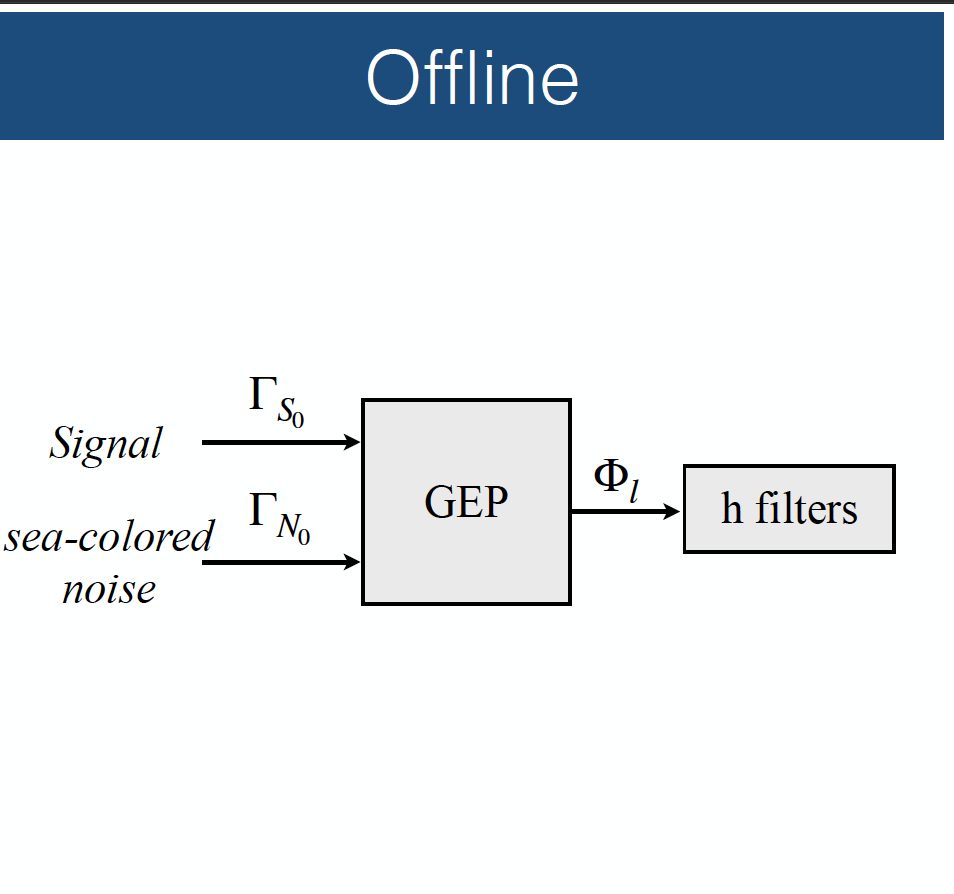

clearvars   
close all
clc

addpath Functions
addpath Offline_saved

Choose if the output is saved or not

Save = 'On';
disp(['Save is: ' Save])

Save is: On


## Background noise simulation 

fs = 100; % (Hz) sampling frequency
duration =  30.00; % (min) duration of the simulated noise 
M = duration*60*fs+1; % Number of samples

% White noise generation
noise = randn(1,M); noise = noise/max(abs(noise));

% Add the slope in frequency
[Noise,nu] = leafft(noise,fs);
slope = -0.04e-3*abs(nu);
Noise = Noise + slope;
for i = 1:M
    if Noise(i) <= 0, Noise(i) = 0 ; end
end
noise = real(ifft(noise)); % Back to time domain

## Noise covariance matrix

% Load signal cov matrix to have the right size
load s_whale.mat ;
N = length(covs);

% Noise covariance matrix
[covn, Qmax] = SMF_noise_preprocess(noise/max(abs(noise)), N);

## Filter bank generation

The filter bank is generated based on the Generalized eigenvalue problem putting in relation the signal and the noise covariance matrix

[hzcall] = SMF_GEP(vecs, covs, covn, Qmax);

## Plot filter spectrum

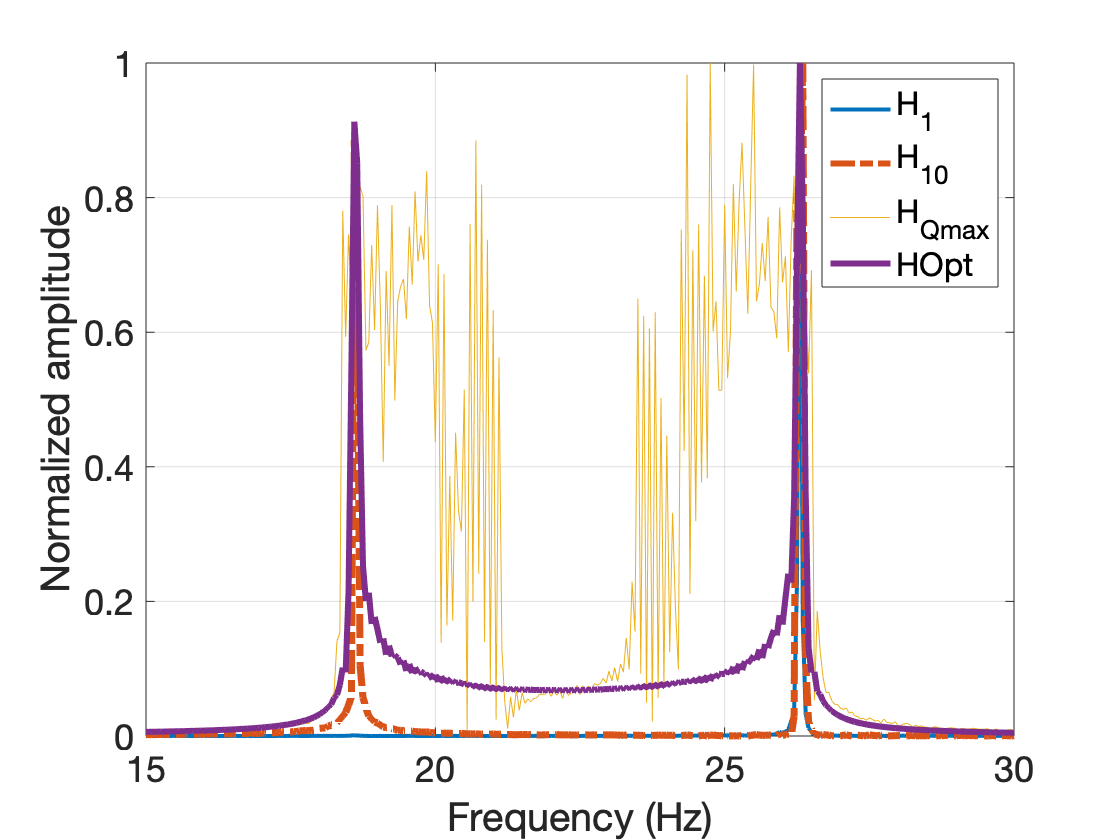

% The optimal filter is the reference signal
[Hopt,nu] = leafft(s_whale,fs);
Hopt_filt = sgolayfilt(Hopt,3,5);

% Spectrum of filters Q = 1, Q = 10 and Q = Qmax = 201
[H1,~] = leafft(hzcall(:,1),fs);
[H10,~] = leafft(hzcall(:,10),fs);
[HQmax,~] = leafft(hzcall(:,Qmax),fs);

% Plot
fig = figure;
plot(nu,H1/max(H1),'Linewidth',2)
hold on
plot(nu,H10/max(H10),'LineStyle','-.','Linewidth',3)
plot(nu,HQmax/max(HQmax))
plot(nu, Hopt_filt/max(Hopt_filt),'LineStyle','-','Linewidth',3)
legend('H_1','H_{10}','H_{Qmax}','HOpt')
xlabel('Frequency (Hz)')
ylabel('Normalized amplitude')
grid on
xlim([15 30])
set(gca, 'fontsize', 18);

## Save the filter bank

h = hzcall;
switch Save
    case 'On'
        save('Offline_saved/filtre_lambda.mat', 'h')
        disp('Matrix saved in: Offline_saved/filtre_lambda.mat')
    case 'Off' 
        disp('Matrix not saved')
    otherwise warning('Uknown Save command - matrix not saved')
end

Matrix saved in: Offline_saved/filtre_lambda.mat
